## [K-Means Clustering](https://apmonitor.com/pds/index.php/Main/KMeansClustering)

K-means clustering is a type of unsupervised machine learning algorithm that is used to identify clusters within a dataset. The goal of K-means clustering is to divide the data into a specified number of clusters (*K*) in a way that minimizes the variance within each cluster.

The algorithm works by first initializing *K* centroids, which are randomly selected points within the data. The data points are then assigned to their closest centroid, and the centroids are updated to the mean of the points assigned to them. This process is repeated until the centroids no longer move or the maximum number of iterations is reached.

Mathematically, the K-means clustering algorithm can be described as follows. Let $x_1 ,x_2 ,\ldotp \ldotp \ldotp ,x_n$ be the data points, where $x_i \in R^d$ is a *d*-dimensional vector. Let $c_1 ,c_2 ,\ldotp \ldotp \ldotp ,c_n$ be the centroids, where $c_j \in R^d$ is also a *d*-dimensional vector. The K-means algorithm works by iteratively updating the centroids and assigning each data point to its closest centroid.

The assignment step is defined as follows:


$$y_i =\arg \;\min_{j\in 1,2,\ldotp \ldotp \ldotp ,k} {\left\|x_i -c_j \right\|}^2$$


This step assigns each data point *x**i* to the cluster whose centroid is closest to it, as measured by the Euclidean distance.

The update step is defined as follows:

 
$$c_j =\frac{1}{\left|S_j \right|}\sum_{i\;\in {\;S}_j } x_i$$


This step updates the centroid of each cluster to be the mean of the data points assigned to it. $S_j$ is the set of indices of the data points assigned to cluster *j*. The algorithm terminates when the centroids no longer move or when the maximum number of iterations is reached.

The main hyper-parameter is to specify how many possible clusters (or *K*) there are in the dataset. The algorithm then iteratively moves the *K*-centers and selects the datapoints that are closest to that centroid in the cluster.

**Advantages:** The most common and simplest clustering algorithm.

**Disadvantages:** Must specify the number of clusters although this can typically be determined by increasing the number of clusters until the objective function does not change significantly.

### Create the data

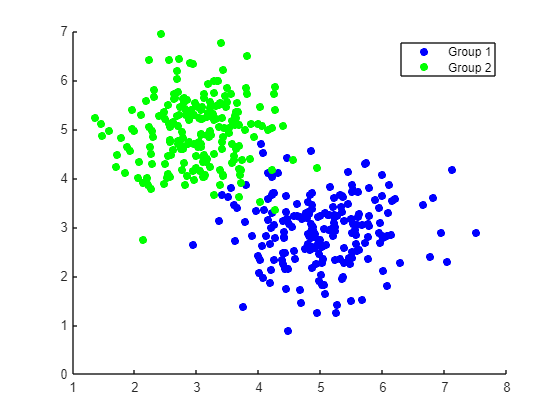

dataSize = 400; % Determine the data size
std = 0.7; % Determine the data standard deviation
n = dataSize/2; % Determine the size of each group
x1 = (randn(n,1)*std) + 5;
y1 = (randn(n,1)*std) + 3;
l1 = ones(n,1);
x2 = (randn(n,1)*std) + 3;
y2 = (randn(n,1)*std) + 5;
l2 = ones(n,1) * 2;

% Organize the data into arrays
x = [x1;x2];
y = [y1;y2];
data = [x,y];
label = [l1;l2];

% Organize the data into a table
data_complete = table(x,y,label, 'VariableNames', {'x', 'y', 'label'});

% Plot the data
figure;
scatter(x1,y1,'filled', 'blue')
hold on
scatter(x2,y2,'filled', 'green')
legend('Group 1', 'Group 2')
hold off

### Predict using K-Means Clustering

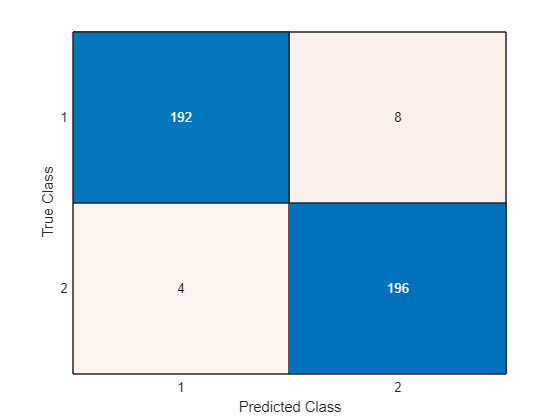

n_clusters = 2; % Store the number of clusters
[cI, ~] = kmeans(data,n_clusters); % Create a k-means model
% Check and possibly reverse labels
if sum(cI ~= label) > (n/4)
    % Reverse the labels if the number of misclassified points is large
    Idx2 = (cI == 2);
    Idx1 = (cI == 1);
    cI(Idx1) = 2;
    cI(Idx2) = 1;
end
% Display the results
confusionchart(label,cI)

### Plot the Results

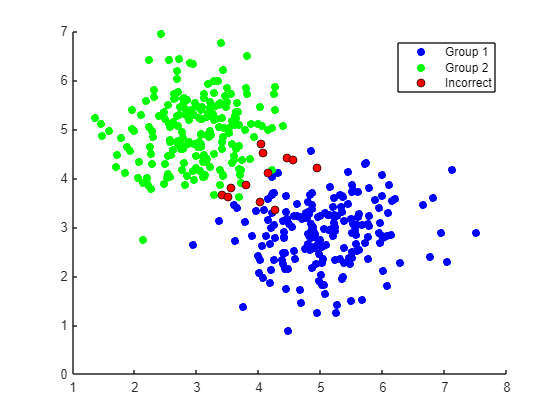

% Get the indicies of the correct predictions
correct = (label == cI);
Idx1 = (cI == 1);
Idx2 = (cI == 2);

figure;
scatter(x(Idx1),y(Idx1),'filled','blue')
hold on
scatter(x(Idx2),y(Idx2), 'filled', 'green')
scatter(x(~correct), y(~correct), 'filled', 'red', 'MarkerEdgeColor', 'black')
legend('Group 1', 'Group 2', 'Incorrect')
hold off

The K-Means Clustering successfully classified two groups that closely resemble the original ones. Although, there were a few incorrect predictions made inbetween the two clusters. This is to be expected because the algorithm is unsupervised and was given no way to differentiate between the groups other than proximity to a cluster.  

The image below shows a few more examples of data predictions made using K-Means Clustering. 

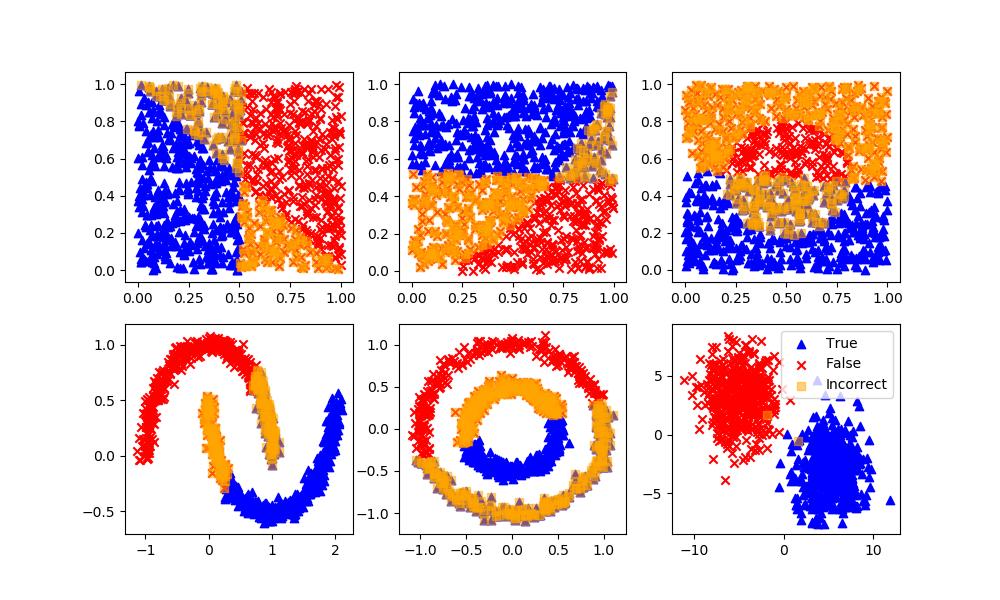

### Further Reading

[k-Means Clustering - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/stats/k-means-clustering.html)

[k-means clustering - MATLAB kmeans (mathworks.com)](https://www.mathworks.com/help/stats/kmeans.html)